BPnetworkProExpressionForecasting

Shuai Yang

2023/3/1

采用 newff 函数 需要在建立神经网络之前对数据进行归一化

%% 
close all
clear
clc
% warning off

load('R1.mat');

idx = randperm(size(R1,1));
% 训练集
P_train = R1(idx(1:4200),1:6)';
T_train = R1(idx(1:4200),7)';
M = size(P_train,2);% 训练集数目
% 测试集
P_test = R1(idx(4201:end),1:6)';
T_test = R1(idx(4201:end),7)';
N = size(P_test,2);% 训练集数目

%对于大多数网络，包括 feedforwardnet，数据归一化是自动执行的，因此只需使用 sim 命令。
% 数据归一化
[p_train,ps_input] = mapminmax(P_train,0,1);
p_test = mapminmax('apply',P_test,ps_input);

[t_train,ps_output] = mapminmax(T_train,0,1);
t_test = mapminmax('apply',T_test,ps_output);

%创建网络
net = newff(p_train,t_train,[12,12]);
% net = newff(p_train,t_train,[10,12]);

% view(net);

% 设置训练参数
net.trainParam.epochs = 1000;   % 迭代次数
net.trainParam.goal = 1e-7;     % 误差阈值
net.trainParam.max_fail = 100; % 交叉验证次数
% 'trainlm'算法 没有学习率的设置 'traingdx' 有lr参数

% 训练网络
net = train(net, p_train, t_train);


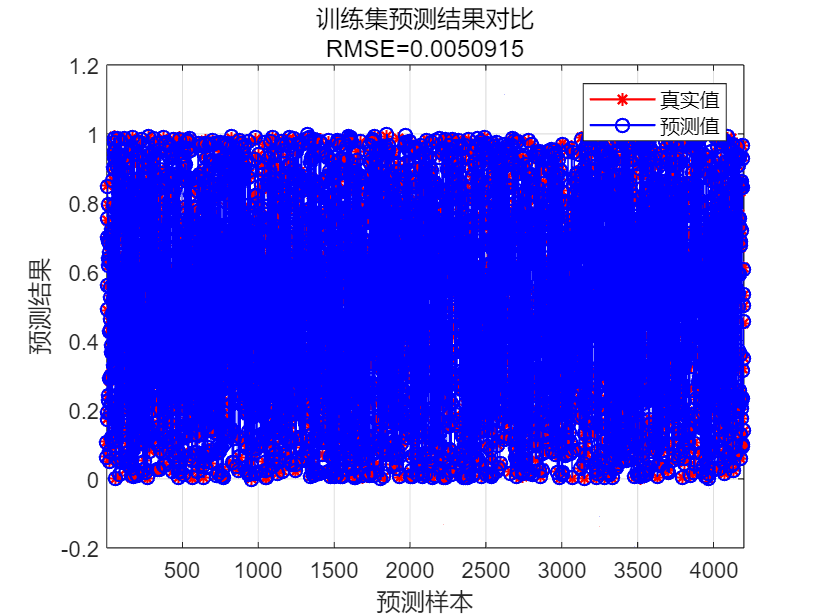

% 仿真测试
t_sim1 = sim(net, p_train);
t_sim2 = sim(net, p_test);
% 数据反归一化
T_sim1 = mapminmax('reverse',t_sim1,ps_output);
T_sim2 = mapminmax('reverse',t_sim2,ps_output);
% 均方误差
error1 = sqrt(sum((T_sim1 - T_train).^2)./M);
error2 = sqrt(sum((T_sim2 - T_test).^2)./N);

% plot 可视化
f1 = figure;
plot(1:M, T_train, 'r-*', 1:M, T_sim1,'b-o','LineWidth', 1)
legend('真实值','预测值')
xlabel('预测样本')
ylabel('预测结果')
string = {'训练集预测结果对比';['RMSE=',num2str(error1)]};
title(string)
xlim([1,M])
grid on

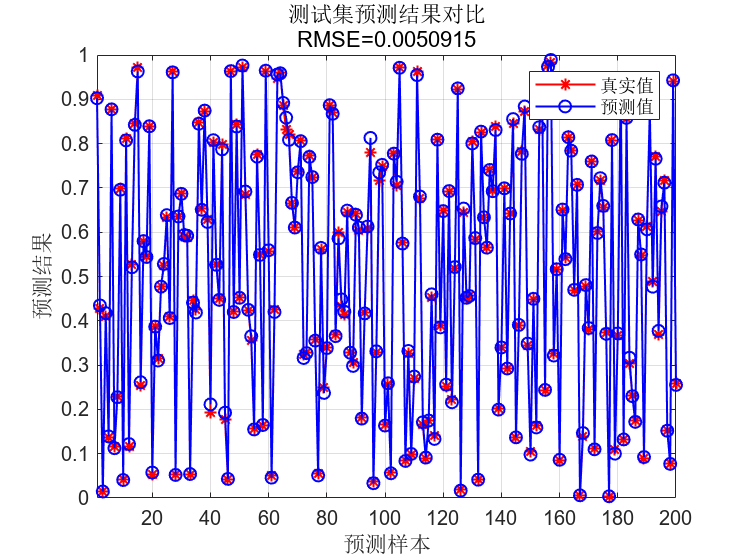


% plot 可视化
f2 = figure;
plot(1:N, T_test, 'r-*', 1:N, T_sim2,'b-o','LineWidth', 1)
legend('真实值','预测值')
xlabel('预测样本')
ylabel('预测结果')
string = {'测试集预测结果对比';['RMSE=',num2str(error1)]};
title(string)
xlim([1,N])
grid on

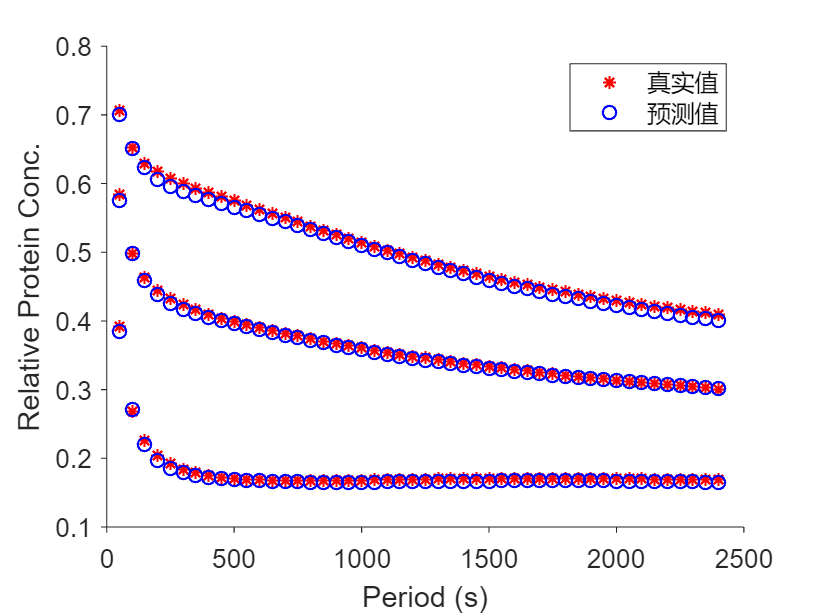

% 数据预测
load('predData.mat')
N_test = predData(:,1:6)';
n_test = mapminmax('apply',N_test,ps_input);
t_sim3 = sim(net, n_test);
T_sim3 = mapminmax('reverse',t_sim3,ps_output);

f1 = figure;
ax1 = axes('Parent',f1);
plot(predData(:,1),predData(:,end),'r-*',...
    predData(:,1),T_sim3,'b-o','LineStyle','none','LineWidth',1)
legend('真实值','预测值')
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')